%% Figure for Section 3.3
% Piotrkowska OSM-derived scenario construction - final 2x2 version
%
% (a) OSM footprints over map
% (b) Selected ROI
% (c) Static scatterers
% (d) Final ISAC scenario
%
% Recommended filename:
% makeFigure_Piotrkowska_OSM_Construction_2x2_Map.m

clear;
close all;
clc;

%% ------------------------------------------------------------------------
%  Files and scenario configuration
%  ------------------------------------------------------------------------

geojsonFile      = "piotrkowska_buildings_raw.geojson";
matOutputFile    = "piotrkowska_buildings_local.mat";
scattererMatFile = "piotrkowska_osm_scatterers.mat";

% ROI: [xMin xMax; yMin yMax]
scenarioROI = [-50 50;
               -50 50];

scattererSpacing = 2; % [m]

% Bistatic Piotrkowska configuration
txPos     = [-10; -40; 0];
rxPos     = [-20;  40; 0];
lookPoint = [-10;   0; 0];

% Target trajectories
target1Start = [-10; -25; 0];
target1End   = [-10;  25; 0];

target2Start = [ 15; -30; 0];
target2End   = [ 15;  30; 0];

%% ------------------------------------------------------------------------
%  Read GeoJSON for geographic map panel
%  ------------------------------------------------------------------------

if ~isfile(geojsonFile)
    error("GeoJSON file not found: %s", geojsonFile);
end

buildingsGT = readgeotable(geojsonFile);

%% ------------------------------------------------------------------------
%  Load or create local OSM building coordinates
%  ------------------------------------------------------------------------

if isfile(matOutputFile)
    S = load(matOutputFile);

    if isfield(S, "osmLocal")
        osmLocal = S.osmLocal;
    else
        fprintf("MAT file found but osmLocal not found. Recomputing local OSM coordinates...\n");
        osmLocal = helperConvertOSMBuildingsToLocalXY(geojsonFile, matOutputFile);
    end
else
    fprintf("Local OSM MAT file not found. Converting GeoJSON to local coordinates...\n");
    osmLocal = helperConvertOSMBuildingsToLocalXY(geojsonFile, matOutputFile);
end

if ~isfield(osmLocal, "buildings")
    error("osmLocal does not contain the field 'buildings'.");
end

%% ------------------------------------------------------------------------
%  Load or generate static scatterers
%  ------------------------------------------------------------------------

if isfile(scattererMatFile)
    S = load(scattererMatFile);

    if isfield(S, "scattererPositions")
        scattererPositions = S.scattererPositions;
    else
        fprintf("Scatterer MAT file found but scattererPositions not found. Regenerating scatterers...\n");

        [scattererPositions, reflectionCoefficients] = ...
            helperGenerateOSMBuildingScatterersFromROI(osmLocal, scenarioROI, scattererSpacing);

        save(scattererMatFile, ...
            "scattererPositions", ...
            "reflectionCoefficients", ...
            "scenarioROI", ...
            "scattererSpacing");
    end
else
    fprintf("Scatterer MAT file not found. Generating scatterers from OSM building contours...\n");

    [scattererPositions, reflectionCoefficients] = ...
        helperGenerateOSMBuildingScatterersFromROI(osmLocal, scenarioROI, scattererSpacing);

    save(scattererMatFile, ...
        "scattererPositions", ...
        "reflectionCoefficients", ...
        "scenarioROI", ...
        "scattererSpacing");
end

%% ------------------------------------------------------------------------
%  Convert scatterers to Nx2 plotting format
%  ------------------------------------------------------------------------

if size(scattererPositions, 1) == 3
    scattererXY = scattererPositions(1:2, :).';

elseif size(scattererPositions, 2) >= 2
    scattererXY = scattererPositions(:, 1:2);

else
    error("scattererPositions has an unexpected size. Expected 3xN or Nx2/Nx3.");
end

roiX = scenarioROI(1,:);
roiY = scenarioROI(2,:);

% Keep only scatterers inside ROI for plotting
insideROI = scattererXY(:,1) >= roiX(1) & scattererXY(:,1) <= roiX(2) & ...
            scattererXY(:,2) >= roiY(1) & scattererXY(:,2) <= roiY(2);

scattererXY = scattererXY(insideROI, :);

fprintf("Number of plotted static scatterers inside ROI: %d\n", size(scattererXY, 1));

Number of plotted static scatterers inside ROI: 573



%% ------------------------------------------------------------------------
%  Determine which buildings intersect the ROI
%  ------------------------------------------------------------------------

nBuildings = numel(osmLocal.buildings);
selectedBuildings = false(nBuildings, 1);

for iB = 1:nBuildings

    x = osmLocal.buildings(iB).x(:);
    y = osmLocal.buildings(iB).y(:);

    valid = ~(isnan(x) | isnan(y));
    x = x(valid);
    y = y(valid);

    if isempty(x)
        continue;
    end

    bboxOverlap = max(x) >= roiX(1) && min(x) <= roiX(2) && ...
                  max(y) >= roiY(1) && min(y) <= roiY(2);

    selectedBuildings(iB) = bboxOverlap;
end

selectedIdx = find(selectedBuildings);

fprintf("Number of building footprints intersecting ROI: %d\n", numel(selectedIdx));

Number of building footprints intersecting ROI: 17


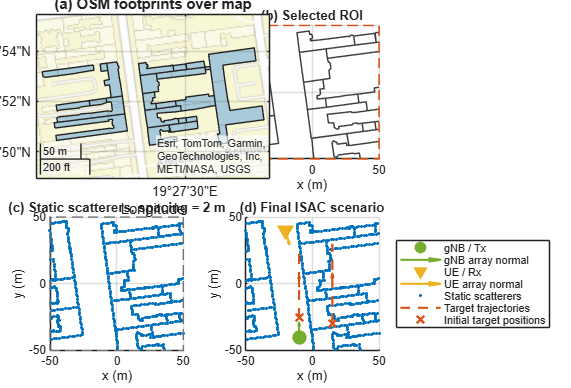


%% ------------------------------------------------------------------------
%  Figure style
%  ------------------------------------------------------------------------

set(groot, "defaultAxesFontSize", 10);
set(groot, "defaultTextFontSize", 10);

buildingGrey       = [0.25 0.25 0.25];
buildingLightGrey  = [0.70 0.70 0.70];
scattererBlue      = [0.0000 0.4470 0.7410];
gNBGreen           = [0.4660 0.6740 0.1880];
ueYellow           = [0.9290 0.6940 0.1250];
targetOrange       = [0.8500 0.3250 0.0980];
roiRed             = [0.8500 0.3250 0.0980];

fig = figure( ...
    "Color", "w", ...
    "Name", "Piotrkowska OSM scenario construction", ...
    "Units", "pixels", ...
    "Position", [100 80 1250 850]);

tl = tiledlayout(fig, 2, 2, ...
    "TileSpacing", "compact", ...
    "Padding", "compact");

%% ------------------------------------------------------------------------
%  (a) OSM footprints over map
%  ------------------------------------------------------------------------
% Robust method: reserve tile 1, delete normal axes, place geoaxes there.

axDummy = nexttile(tl, 1);
tilePos = axDummy.Position;
delete(axDummy);

gx = geoaxes("Parent", fig, "Position", tilePos);

geoplot(gx, buildingsGT.Shape, ...
    "LineWidth", 1.0);

geobasemap(gx, "streets");

title(gx, "(a) OSM footprints over map");
gx.FontSize = 10;

%% ------------------------------------------------------------------------
%  (b) Selected ROI
%  ------------------------------------------------------------------------

ax2 = nexttile(tl, 2);
hold(ax2, "on");
grid(ax2, "on");
axis(ax2, "equal");

plotBuildingContours(ax2, osmLocal.buildings, selectedIdx, buildingGrey, 1.1);

rectangle(ax2, ...
    "Position", [roiX(1), roiY(1), diff(roiX), diff(roiY)], ...
    "EdgeColor", roiRed, ...
    "LineWidth", 1.2, ...
    "LineStyle", "--");

xlim(ax2, roiX);
ylim(ax2, roiY);

xlabel(ax2, "x (m)");
ylabel(ax2, "y (m)");
title(ax2, "(b) Selected ROI");

hold(ax2, "off");

%% ------------------------------------------------------------------------
%  (c) Generated static scatterers
%  ------------------------------------------------------------------------

ax3 = nexttile(tl, 3);
hold(ax3, "on");
grid(ax3, "on");
axis(ax3, "equal");

% Light building contours in the background
plotBuildingContours(ax3, osmLocal.buildings, selectedIdx, buildingLightGrey, 0.9);

% Static scatterers
plot(ax3, scattererXY(:,1), scattererXY(:,2), ...
    ".", ...
    "Color", scattererBlue, ...
    "MarkerSize", 7, ...
    "DisplayName", "Static scatterers");

rectangle(ax3, ...
    "Position", [roiX(1), roiY(1), diff(roiX), diff(roiY)], ...
    "EdgeColor", [0.45 0.45 0.45], ...
    "LineWidth", 1.0, ...
    "LineStyle", "--");

xlim(ax3, roiX);
ylim(ax3, roiY);

xlabel(ax3, "x (m)");
ylabel(ax3, "y (m)");
title(ax3, "(c) Static scatterers, spacing = 2 m");

hold(ax3, "off");

%% ------------------------------------------------------------------------
%  (d) Final ISAC scenario
%  ------------------------------------------------------------------------

ax4 = nexttile(tl, 4);
hold(ax4, "on");
grid(ax4, "on");
axis(ax4, "equal");

% Static scatterers
hScat = plot(ax4, scattererXY(:,1), scattererXY(:,2), ...
    ".", ...
    "Color", scattererBlue, ...
    "MarkerSize", 7, ...
    "DisplayName", "Static scatterers");

% gNB / Tx
hTx = plot(ax4, txPos(1), txPos(2), ...
    "o", ...
    "MarkerSize", 10, ...
    "MarkerFaceColor", gNBGreen, ...
    "MarkerEdgeColor", gNBGreen, ...
    "DisplayName", "gNB / Tx");

% UE / Rx
hRx = plot(ax4, rxPos(1), rxPos(2), ...
    "v", ...
    "MarkerSize", 10, ...
    "MarkerFaceColor", ueYellow, ...
    "MarkerEdgeColor", ueYellow, ...
    "DisplayName", "UE / Rx");

% Array normal arrows
hTxNorm = drawLookArrow(ax4, txPos, lookPoint, 11, gNBGreen, "gNB array normal");
hRxNorm = drawLookArrow(ax4, rxPos, lookPoint, 11, ueYellow, "UE array normal");

% Target trajectories
hTraj = plot(ax4, ...
    [target1Start(1) target1End(1)], ...
    [target1Start(2) target1End(2)], ...
    "--", ...
    "Color", targetOrange, ...
    "LineWidth", 1.6, ...
    "DisplayName", "Target trajectories");

plot(ax4, ...
    [target2Start(1) target2End(1)], ...
    [target2Start(2) target2End(2)], ...
    "--", ...
    "Color", targetOrange, ...
    "LineWidth", 1.6, ...
    "HandleVisibility", "off");

% Direction arrows on target trajectories
drawTrajectoryArrow(ax4, target1Start, target1End, targetOrange);
drawTrajectoryArrow(ax4, target2Start, target2End, targetOrange);

% Initial target positions
hTargetStart = plot(ax4, target1Start(1), target1Start(2), ...
    "x", ...
    "Color", targetOrange, ...
    "LineWidth", 1.8, ...
    "MarkerSize", 8, ...
    "DisplayName", "Initial target positions");

plot(ax4, target2Start(1), target2Start(2), ...
    "x", ...
    "Color", targetOrange, ...
    "LineWidth", 1.8, ...
    "MarkerSize", 8, ...
    "HandleVisibility", "off");

xlim(ax4, roiX);
ylim(ax4, roiY);

xlabel(ax4, "x (m)");
ylabel(ax4, "y (m)");
title(ax4, "(d) Final ISAC scenario");

% Legend outside the plot to keep the scenario clean
legend(ax4, ...
    [hTx, hTxNorm, hRx, hRxNorm, hScat, hTraj, hTargetStart], ...
    "Location", "eastoutside");

hold(ax4, "off");

%% ------------------------------------------------------------------------
%  Export
%  ------------------------------------------------------------------------

if ~isfolder("figures")
    mkdir("figures");
end

exportgraphics(fig, ...
    fullfile("figures", "piotrkowska_osm_scenario_construction_final.pdf"), ...
    "ContentType", "vector");

exportgraphics(fig, ...
    fullfile("figures", "piotrkowska_osm_scenario_construction_final.png"), ...
    "Resolution", 300);


fprintf("\nFigure exported to:\n");


Figure exported to:


fprintf("  figures/piotrkowska_osm_scenario_construction_final.pdf\n");

  figures/piotrkowska_osm_scenario_construction_final.pdf


fprintf("  figures/piotrkowska_osm_scenario_construction_final.png\n");

  figures/piotrkowska_osm_scenario_construction_final.png



%% ------------------------------------------------------------------------
%  Local helper functions
%  ------------------------------------------------------------------------

function plotBuildingContours(ax, buildings, idx, lineColor, lineWidth)

    if islogical(idx)
        idx = find(idx);
    end

    if isempty(idx)
        return;
    end

    for iB = idx(:).'

        x = buildings(iB).x;
        y = buildings(iB).y;

        if isempty(x) || isempty(y)
            continue;
        end

        plot(ax, x, y, ...
            "Color", lineColor, ...
            "LineWidth", lineWidth);
    end
end

function h = drawLookArrow(ax, nodePos, lookPoint, arrowLength, arrowColor, displayName)

    dirVec = lookPoint(1:2) - nodePos(1:2);
    n = norm(dirVec);

    if n < eps
        h = plot(ax, NaN, NaN, ...
            "-", ...
            "Color", arrowColor, ...
            "DisplayName", displayName);
        return;
    end

    dirVec = arrowLength * dirVec / n;

    h = quiver(ax, ...
        nodePos(1), nodePos(2), ...
        dirVec(1), dirVec(2), ...
        0, ...
        "Color", arrowColor, ...
        "LineWidth", 1.6, ...
        "MaxHeadSize", 0.8, ...
        "DisplayName", displayName);
end

function drawTrajectoryArrow(ax, pStart, pEnd, arrowColor)

    pStart = pStart(:);
    pEnd   = pEnd(:);

    p0 = pStart(1:2);
    p1 = pEnd(1:2);

    direction = p1 - p0;

    arrowStart = p0 + 0.45 * direction;
    arrowStep  = 0.18 * direction;

    quiver(ax, ...
        arrowStart(1), arrowStart(2), ...
        arrowStep(1), arrowStep(2), ...
        0, ...
        "Color", arrowColor, ...
        "LineWidth", 1.5, ...
        "MaxHeadSize", 1.2, ...
        "HandleVisibility", "off");
end